%clc
clear all

## Read the data

% files=dir('*RSS*.txt');
% data_read=[];
% num_file =length(files);
% sample_size=num_file*4;
% for i=1:num_file
%     sub_data=string(importdata(files(i).name));
%     data_read=[data_read;sub_data];
% end
% [raw_macs,raw_rsses,raw_labels]=split_data(data_read);
% data=[raw_macs,raw_rsses,raw_labels];

## Filter out data with small value

% raw_sample_size=length(raw_labels);
% threshold=-50;
% macs=[];
% rsses=[];
% labels=[];
% for i=1:raw_sample_size
%     if str2double(raw_rsses(i))>=threshold
%         macs=[macs; raw_macs(i)];
%         rsses=[rsses; raw_rsses(i)];
%         labels=[labels; raw_labels(i)];
%     end
% end
% uniqe_mac = unique(macs).';
% num_line=length(labels);
% num_feature=length(uniqe_mac);


## Rearrange the data

% labels_cleaned=zeros(num_line,1);
% % A->0 B->1 C->2 D->3
% for i=1:num_line
%     switch labels(i)
%         case "A"
%             labels_cleaned(i)=0;
%         case "B"
%             labels_cleaned(i)=1;
%         case "C"
%             labels_cleaned(i)=2;
%         case "D"
%             labels_cleaned(i)=3;
%     end
% end
% data_cleaned=[macs rsses labels_cleaned];
%data_cleaned=[data_cleaned,zeros(length(labels),1)];
% mac1 mac2 .....macn label
% for i=1:num_line
%     line=zeros(1,num_feature+1);
%     %find the index of the mac in the feature space
%     index=findFeatureIndex(uniqe_mac,macs(i));
%     if index >=0
%         data_cleaned(i,index)=rsses(i);
%     end
%     data_cleaned(i,end)=labels_cleaned(i);
% end
% sample=zeros(sample_size,num_feature+1);
% for i=1:sample_size
%     
% end
 sel_feature_num=40

sel_feature_num = 40

 data=load("data_loc_all.txt")

data =   -100  -100  -100  -100  -100   -61   -59  -100  -100  -100   -77  -100  -100  -100  -100  -100  -100  -100   -66  -100  -100  -100   -36   -31  -100   -52   -45  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100   -77   -49  -100  -100  -100  -100   -75  -100  -100  -100
  -100  -100  -100  -100  -100   -70   -67  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100   -44   -33  -100   -59   -48  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100   -61  -100  -100  -100  -100  -100  -100  -100  -100
  -100  -100   -81  -100  -100  -100   -71  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100   -37   -54  -100   -63   -59  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100   -65  -100  -100  -100  -100  -100  -100  -100  -100
  -100  -100   -76  -100  -100   -65   -65  -100  -100  -100  -100  -100  -100  -100  -100

 %macs=load("chosen_macs.txt")
 randIndex = randperm(size(data,1));
 data=data(randIndex,:);
 sample = data(:,1:end-1);
 target =data(:,end);
 [idx,scores] = fscmrmr(sample,target);
 %classificationLearner
 feature_selected=idx(1:sel_feature_num)

feature_selected =    107    93   100    88   105    37    30    73    29    20    70    17    74    99   125    16    49    89    54     9   124    33    86     1   128   114    64   117    82   115    28     4     2   118    60   108    24    66   101    72


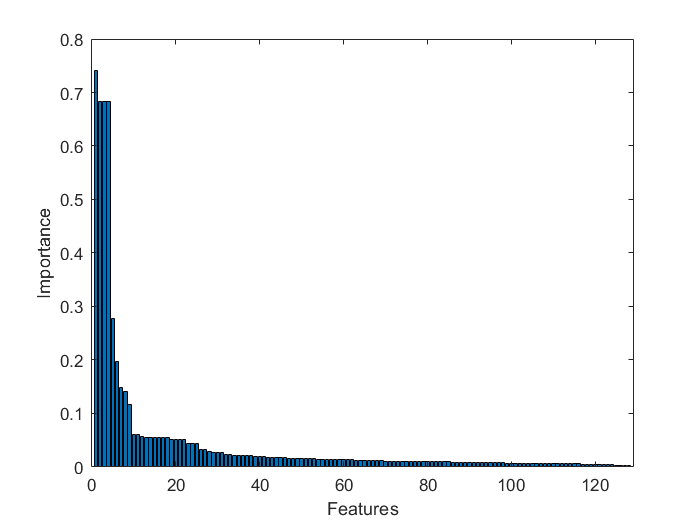

 
 bar(scores(idx))
xlabel('Features')
ylabel('Importance')

 %% Clean Features
  
 data_selected=data(:,idx(1:sel_feature_num))

data_selected =    -59  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100   -51  -100  -100  -100
   -74  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100   -75  -100  -100  -100   -76  -100  -100   -29  -100  -100  -100
   -81  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100   -76  -100  -100  -100  -100  -100  -100   -32  -100   -80  -100
   -78  -100  -100  -100  -100  -100  -100  -100   -75  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100   -75  -100  -100  -100  -100  -100  -100   -32  -100  -100  -100
   -66  -100  -100  

 data_selected=[data_selected target]

data_selected =    -59  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100   -51  -100  -100  -100     2
   -74  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100   -75  -100  -100  -100   -76  -100  -100   -29  -100  -100  -100     0
   -81  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100   -76  -100  -100  -100  -100  -100  -100   -32  -100   -80  -100     0
   -78  -100  -100  -100  -100  -100  -100  -100   -75  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100  -100   -75  -100  -100  -100  -100  -100  -100   -32  -100  -100  -100   

  save('data_loc.txt','data_selected','-ascii');
  idx(1:sel_feature_num)

ans =    107    93   100    88   105    37    30    73    29    20    70    17    74    99   125    16    49    89    54     9   124    33    86     1   128   114    64   117    82   115    28     4     2   118    60   108    24    66   101    72


  PYTHON_idx=idx(1:sel_feature_num)-1

PYTHON_idx =    106    92    99    87   104    36    29    72    28    19    69    16    73    98   124    15    48    88    53     8   123    32    85     0   127   113    63   116    81   114    27     3     1   117    59   107    23    65   100    71
